# Practice Problems

## Problem 1

Solve $e^{-x} =x$, using a routine of your choice that we developed in class.  Then check your result with the corresponding MATLAB function

% Your code goes here
clc; clear; clf;

f=@(x) exp(-x)-x;
fplot(f,[-2,5]); grid on; xlabel('x axis'); ylabel('y axis'); title('Problem 1');
% Prepare for Bisection
ax=[0];
cx=[1];
% --------- Bisection -------------
for m=1:length(ax)
    a=ax(m);
    c=cx(m);
    for n=1:40
        b=(a+c)/2;
        hold on;plot(b,f(b),'*r');hold off;
        if f(b)==0
            a=b;
            c=b;
            break;
        elseif f(a)*f(b)<0
            c=b;
        else
            a=b;
        end
    end
fprintf('Using Bisection: x%i = %3.3f and y%i = %3.3f',m,b,m,f(b))
hold on;plot(b,f(b),'ok');hold off;
end

Using Bisection: x1 = 0.567 and y1 = -0.000


% -------------- Newtons method -----------------
x0=0;
dfdx=@(x) -exp(-x)-1;
for j=1:length(x0)
    for n=1:10
        x=x0-f(x0)./dfdx(x0);
        x0=x;
    end
    fprintf('Using Newtons Method solution %i : x = %3.3f and y = %3.3f',j,x0,f(x0))
    hold on; plot(x0,f(x0),'.y'); hold off;
end

Using Newtons Method solution 1 : x = 0.567 and y = -0.000

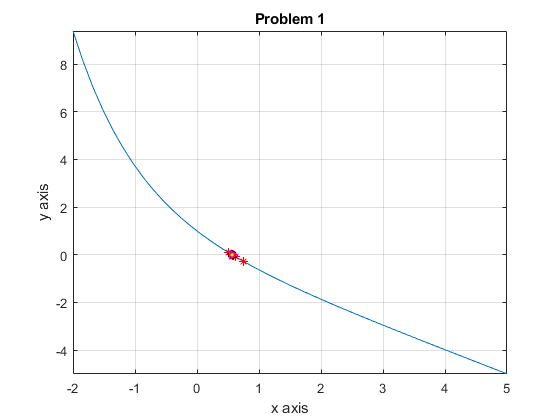

Using fzero: x1 = 0.567 and y1 = 0.000


% ----------------- fzero -------------------
for i=1:length(ax)
xsoln=fzero(f,[ax(i),cx(i)]);
fprintf('Using fzero: x%i = %3.3f and y%i = %3.3f',i,xsoln,i,f(xsoln))
hold on; plot(xsoln,f(xsoln),'>m'); hold off;
end

## Problem 2

Find the solution to the equation


$$x=\frac{5}{x^2 }+2$$


using a routine of your choice that we developed in class.  Then check your result with the corresponding MATLAB function

% Your code goes here
clc; clear; clf;

f=@(x) 5./x.^2 + 2 -x;
fplot(f,[1.5,4]); grid on; xlabel('x axis'); ylabel('y axis'); title('Problem 2');
% left and right endpoints 
ax=[2.5]; % left endpoint
cx=[3]; % right endpoint

% -------- Bisection --------
for m=1:length(ax)
    a=ax(m);
    c=cx(m);
    for n=1:40
        b=(a+c)/2;
        hold on;plot(b,f(b),'*r');hold off;
        if f(b)==0
            a=b;
            c=b;
            break;
        elseif f(a)*f(b)<0
            c=b;
        else
            a=b;
        end
    end
fprintf('Using Bisection, solution %i: x = %3.3f and y = %3.3f',m,b,f(b))
hold on;plot(b,f(b),'ok');hold off;
end

Using Bisection, solution 1: x = 2.691 and y = -0.000


% ------ False Position ---------
for m=1:length(ax)       % Repeat entire algorithm for each interval
    a=ax(m); c=cx(m);
    
    % Use algorithm   (In this example, we will iterate 20 times.)
    
    for n=1:10
        x=[a c]; %left and right boundary
        y=f(x);
        
        pp=polyfit(x,y,1); % Coefficients of line defined by endpoints
        b=-pp(2)/pp(1);    % Compute intersection of line with x-axis
        % as estimate of solution
        
        if f(b)==0      % Check to see if you have found solution
            a=b; c=b;   % If so, set endpoints of interval to solution
            break;      % if you reach the solution you need to exit the loop
            
        elseif f(a)*f(b)<0  % Check to see if solution is less than midpoint
            c=b;        % If so, set right endpoint to midpoint
        else
            a=b;        % Otherwise solution must be more than midpoint, so
                        % set left endpoint to midpoint
        end
        
    end
    fprintf('Using False Postion, solution %i: x = %3.3f and y = %3.3f',m,b,f(b))
    hold on;plot(b,f(b),'ok');hold off;
end

Using False Postion, solution 1: x = 2.691 and y = -0.000

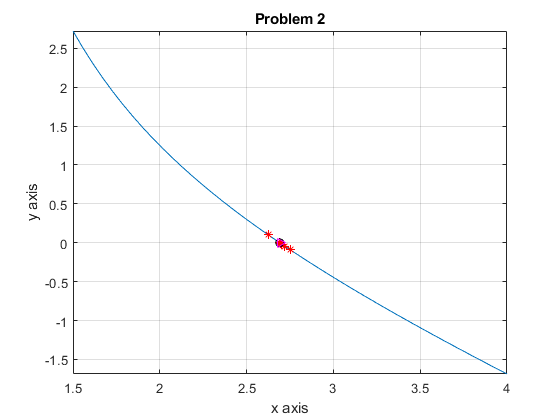

Using fzero, solution 1: x = 2.691 and y = 0.000


% % ---------- Newtons method ------------
% x0=2.5; % guess for x = 0 
% dfdx=@(x) ; % need the derivative
% for j=1:length(x0)
%     for n=1:10
%         x=x0-f(x0)./dfdx(x0);
%         x0=x;
%     end
%     fprintf('Using Newtons Method, solution %i: x = %3.3f and y = %3.3f',j,x0,f(x0))
%     hold on; plot(x0,f(x0),'.y'); hold off;
% end

% ----------------- fzero ----------
for i=1:length(ax)
xsoln=fzero(f,[ax(i),cx(i)]);
fprintf('Using fzero, solution %i: x = %3.3f and y = %3.3f',i,xsoln,f(xsoln))
hold on; plot(xsoln,f(xsoln),'>m'); hold off;
end

## Problem 3

Find the solution to the equation


$$x=\frac{4}{x^2 +3}$$


using a routine of your choice that we developed in class.  Then check your result with the corresponding MATLAB function

% Your code goes here
clc; clear; clf;

f=@(x) 4./(x.^2 +3) - x;
fplot(f,[-5,5]); grid on; xlabel('x axis'); ylabel('y axis'); title('Problem 3');
% left and right endpoints 
ax=[0.1]; % left endpoint
cx=[2]; % right endpoint

% -------- Bisection --------
for m=1:length(ax)
    a=ax(m);
    c=cx(m);
    for n=1:40
        b=(a+c)/2;
        hold on;plot(b,f(b),'*r');hold off;
        if f(b)==0
            a=b;
            c=b;
            break;
        elseif f(a)*f(b)<0
            c=b;
        else
            a=b;
        end
    end
fprintf('Using Bisection, solution %i: x = %3.3f and y = %3.3f',m,b,f(b))
hold on;plot(b,f(b),'ok');hold off;
end

Using Bisection, solution 1: x = 1.000 and y = 0.000


% ------ False Position ---------
for m=1:length(ax)       % Repeat entire algorithm for each interval
    a=ax(m); c=cx(m);
    
    % Use algorithm   (In this example, we will iterate 20 times.)
    
    for n=1:10
        x=[a c];
        y=f(x);
        
        pp=polyfit(x,y,1); % Coefficients of line defined by endpoints
        b=-pp(2)/pp(1);    % Compute intersection of line with x-axis
        % as estimate of solution
        
        if f(b)==0      % Check to see if you have found solution
            a=b; c=b;   % If so, set endpoints of interval to solution
            break;      % if you reach the solution you need to exit the loop
            
        elseif f(a)*f(b)<0  % Check to see if solution is less than midpoint
            c=b;        % If so, set right endpoint to midpoint
        else
            a=b;        % Otherwise solution must be more than midpoint, so
                        % set left endpoint to midpoint
        end
        
    end
    fprintf('Using False Postion, solution %i: x = %3.3f and y = %3.3f',m,b,f(b))
    hold on;plot(b,f(b),'ok');hold off;
end

Using False Postion, solution 1: x = 1.000 and y = 0.000


% ---------- Newtons method ------------
x0=2.5; % guess for x = 1
dfdx=@(x) -8*x./((x.^2+3).^2) - 1; % need the derivative
for j=1:length(x0)
    for n=1:10
        x=x0-f(x0)./dfdx(x0);
        x0=x;
    end
    fprintf('Using Newtons Method, solution %i: x = %3.3f and y = %3.3f',j,x0,f(x0))
    hold on; plot(x0,f(x0),'.y'); hold off;
end

Using Newtons Method, solution 1: x = 1.000 and y = 0.000

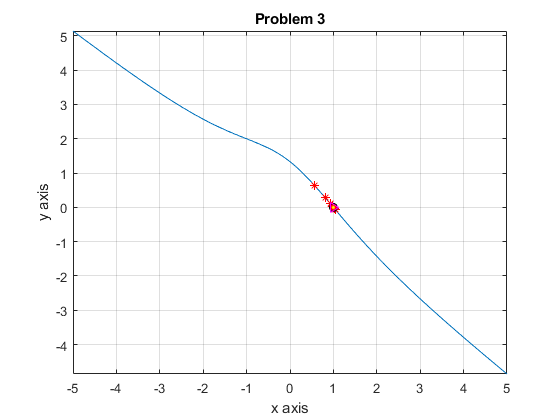

Using fzero, solution 1: x = 1.000 and y = 0.000


% ------------ fzero ----------
for i=1:length(ax)
xsoln=fzero(f,[ax(i),cx(i)]);fprintf('Using fzero, solution %i: x = %3.3f and y = %3.3f',i,xsoln,f(xsoln))
hold on; plot(xsoln,f(xsoln),'>m'); hold off;
end

## Problem 4.

Find the solution(s) to the equation


$$\tan \left(x^3 \right)=x$$


over the domain $x\in \left\lbrack -1,1\right\rbrack$.

using a routine of your choice that we developed in class.  Then check your result with the corresponding MATLAB function

% Your code goes here
clc,clear,clf
% Plot
f=@(x)tan(x.^3)-x;
fplot(f,[-1,1]); grid on; xlabel('x axis'); ylabel('y axis'); title('Problem 4');
% Prepare for Bisection
ax=[-1  -0.1 0.8];
cx=[-0.8 0.1 1.0];
% -------------- Bisection -------------
for m=1:3
    a=ax(m);
    c=cx(m);
    for n=1:40
        b=(a+c)/2;
        hold on;plot(b,f(b),'*r');hold off;
        if f(b)==0
            a=b;
            c=b;
            break;
        elseif f(a)*f(b)<0
            c=b;
        else
            a=b;
        end
    end
fprintf('Using Bisection solution %i: x =%3.3f and y = %3.3f',m,b,f(b))
hold on;plot(b,f(b),'ok');hold off;
end

Using Bisection solution 1: x =-0.902 and y = -0.000

Using Bisection solution 2: x =0.000 and y = 0.000

Using Bisection solution 3: x =0.902 and y = 0.000


% % ------ False Position ---------  % doesnt work with this problem ??
% for m=1:length(ax)       % Repeat entire algorithm for each interval
%     a=ax(m); c=cx(m);
%     
%     % Use algorithm   (In this example, we will iterate 20 times.)
%     
%     for n=1:10
%         x=[a c];
%         y=f(x);
%         
%         pp=polyfit(x,y,6); % Coefficients of line defined by endpoints
%         b=-pp(2)/pp(1);    % Compute intersection of line with x-axis
%         % as estimate of solution
%         
%         if f(b)==0      % Check to see if you have found solution
%             a=b; c=b;   % If so, set endpoints of interval to solution
%             break;      % if you reach the solution you need to exit the loop
%             
%         elseif f(a)*f(b)<0  % Check to see if solution is less than midpoint
%             c=b;        % If so, set right endpoint to midpoint
%         else
%             a=b;        % Otherwise solution must be more than midpoint, so
%                         % set left endpoint to midpoint
%         end
%         
%     end
%     fprintf('Using False Postion, solution %i: x = %3.3f and y = %3.3f',m,b,f(b))
%     hold on;plot(b,f(b),'ok');hold off;
% end

% ----------- Newtons method -------------
x0=[-1 0 0.9];
dfdx=@(x) ((sec(x.^3)).^2).*(3*x.^2) - 1;
for o=1:length(x0)
    for n=1:10
        x=x0-f(x0)./dfdx(x0);
        x0=x;
    end
    fprintf('Using Newtons Method solution %i: x = %3.3f and y = %3.3f',o,x0,f(x0))
    hold on; plot(x0,f(x0),'.y'); hold off;
end

Using Newtons Method solution 1: x = -0.902 and y = 0.000Using Newtons Method solution 9.020255e-01: x = 0.000 and y = 0.000Using Newtons Method solution 0: x = 

Using Newtons Method solution 2: x = -0.902 and y = 0.000Using Newtons Method solution 9.020255e-01: x = 0.000 and y = 0.000Using Newtons Method solution 0: x = 

Using Newtons Method solution 3: x = -0.902 and y = 0.000Using Newtons Method solution 9.020255e-01: x = 0.000 and y = 0.000Using Newtons Method solution 0: x = 

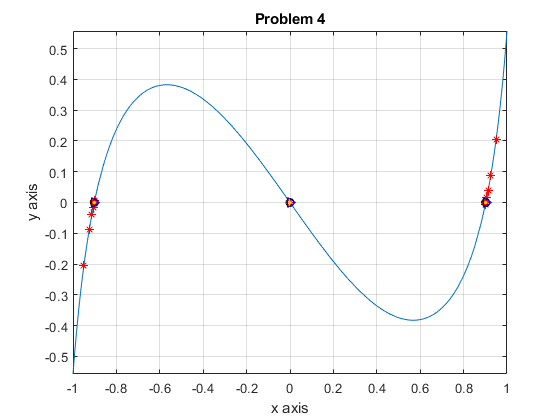

Using fzero solution 1: x = -0.902 and y = 0.000

Using fzero solution 2: x = 0.000 and y = 0.000

Using fzero solution 3: x = 0.902 and y = 0.000



% ------------- fzero ---------------
for i=1:3
xsoln=fzero(f,[ax(i),cx(i)]);
fprintf('Using fzero solution %i: x = %3.3f and y = %3.3f',i,xsoln,f(xsoln))
hold on; plot(xsoln,f(xsoln),'>b'); hold off;
end

## Problem 5

Consider the system


$$x^2 +{4y}^2 =16$$



$$x^2 -2x-y=-1$$


Plot the equations, determine if there are any values of (x,y) that satisfy both of them simultaneously and , if so, find them using Newton's Method.   Check your result using an appropriate MATLAB function.

% your code goes here
clc;clear;clf;
u=@(x,y) x.^2 + 4*y.^2 -16;
v=@(x,y) x.^2 - 2*x - y + 1;

x=linspace(-5,5);
y=linspace(-5,5);
[X,Y]=meshgrid(x,y);
contour(X,Y,u(X,Y),[0,0],'-b'); grid on; title('Problem 5');
hold on; contour(X,Y,v(X,Y),[0,0],'-r'); hold off;

% --------------- Newtons Method ----------------
% determine how many solutions and about where they are
z0=zeros(2,2); zsoln=zeros(2,2);
z0(:,1)=[-0.5,2]; % [x1,y1]
z0(:,2)=[2.1,1.7]; % [x2,y2]
% Jacobian
dudx=@(x,y) 2*x;
dudy=@(x,y) 8*y;
dvdx=@(x,y) 2*x - 2;
dvdy=@(x,y) -1;
J=@(x,y)[dudx(x,y),dudy(x,y);dvdx(x,y),dvdy(x,y)];
Jz=@(z)J(z(1),z(2));
% vectorize
w=@(z) [u(z(1),z(2));v(z(1),z(2))];
% Initialize the estimate and proceed through iterative loop
for m=1:length(z0)                                      %   How many solutions
    zn=z0(:,m);
    hold on; plot(zn(1),zn(2),'*r');hold off; 
    for n=1:10                                          %   Core Algorithm
        zn=zn-Jz(zn)\w(zn);
        hold on; plot(zn(1),zn(2),'*r');hold off;
    end
    zsoln(:,m)=zn;
end
% Display Result
for m=1:length(zsoln)
    W=w(zsoln(:,m));
    fprintf('Newtons Method: solution %i is: x = %6.4f  y = %6.4f   u = %6.4f   v = %6.4f  \n',m,zsoln(1,m),zsoln(2,m),W(1),W(2));
end

Newtons Method: solution 1 is: x = -0.4105  y = 1.9894   u = 0.0000   v = 0.0000  
Newtons Method: solution 2 is: x = 2.2817  y = 1.6427   u = 0.0000   v = 0.0000  


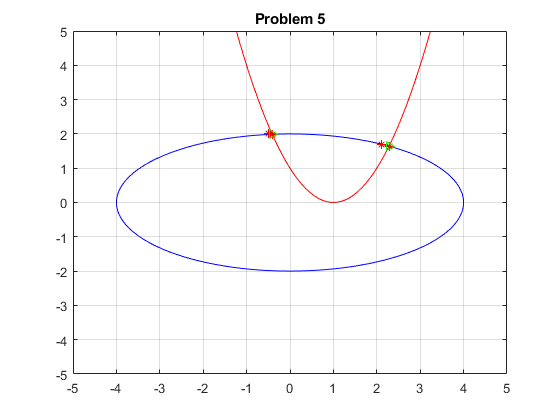


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fsolve: solution 1 is: x = -0.41048 y = 1.98944


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fsolve: solution 2 is: x = 2.28168 y = 1.64271


% ---------------- fsolve -----------------
wz=@(z) [u(z(1),z(2));v(z(1),z(2))];
% Initial guess [x;y]
z1 = [-0.5 2.1;
       2   1.7];
[N,M]=size(z1);
for m=1:M
    z=z1(:,m);
    solution = fsolve(wz,z);
    fprintf('fsolve: solution %i is: x = %5.5f y = %5.5f',m,solution(1),solution(2))
    hold on; plot(solution(1),solution(2),'>g'); hold off;
end

## Problem 6

Consider the system


$$x^2 +y^2 =1$$



$$4x^3 -4y^2 =-1$$


Plot the equations, determine if there are any values of (x,y) that satisfy both of them simultaneously and , if so, find them using Newton's Method.   Check your result using an appropriate MATLAB function.

% your code goes here
clc;clear;clf;
u=@(x,y) x.^2 + y.^2 -1;
v=@(x,y) 4*x.^3 - 4*y.^2 - 1;

x=linspace(-2,2);
y=linspace(-2,2);
[X,Y]=meshgrid(x,y);
contour(X,Y,u(X,Y),[0,0],'-b'); grid on; title('Problem 6');
hold on; contour(X,Y,v(X,Y),[0,0],'-r'); hold off;

% --------------- Newtons Method ----------------
% determine how many solutions and about where they are
z0=zeros(2,2); zsoln=zeros(2,2);
z0(:,1)=[0.7,0.7]; % [x1,y1]
z0(:,2)=[0.7,-0.7]; % [x2,y2]
% Jacobian
dudx=@(x,y) 2*x;
dudy=@(x,y) 2*y;
dvdx=@(x,y) 12*x.^2;
dvdy=@(x,y) -8*y;
J=@(x,y)[dudx(x,y),dudy(x,y);dvdx(x,y),dvdy(x,y)];
Jz=@(z)J(z(1),z(2));
% vectorize
w=@(z) [u(z(1),z(2));v(z(1),z(2))];
% Initialize the estimate and proceed through iterative loop
for m=1:length(z0)                                      %   How many solutions
    zn=z0(:,m);
    hold on; plot(zn(1),zn(2),'*r');hold off; 
    for n=1:10                                          %   Core Algorithm
        zn=zn-Jz(zn)\w(zn);
        hold on; plot(zn(1),zn(2),'*r');hold off;
    end
    zsoln(:,m)=zn;
end
% Display Result
for m=1:length(zsoln)
    W=w(zsoln(:,m));
    fprintf('Newtons Method: solution %i is: x = %6.4f  y = %6.4f   u = %6.4f   v = %6.4f  \n',m,zsoln(1,m),zsoln(2,m),W(1),W(2));
end

Newtons Method: solution 1 is: x = 0.8271  y = 0.5620   u = 0.0000   v = 0.0000  
Newtons Method: solution 2 is: x = 0.8271  y = -0.5620   u = 0.0000   v = 0.0000  


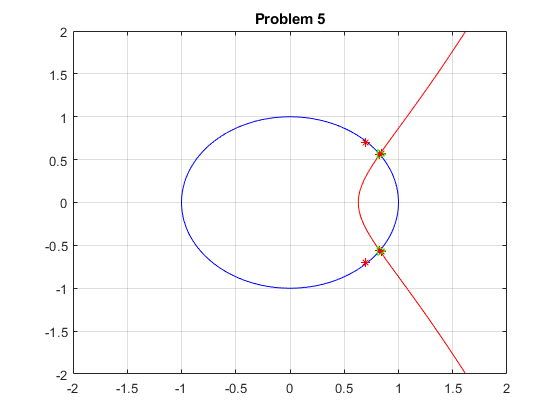


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fsolve: solution 1: x = 0.82712 y = 0.56202


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fsolve: solution 2: x = 0.82712 y = -0.56202


% ---------------- fsolve -----------------
wz=@(z) [u(z(1),z(2));v(z(1),z(2))];
% Initial guess [x;y]
z1 = [0.7 0.7;
      0.7 -0.7];
[N,M]=size(z1);
for m=1:M
    z=z1(:,m);
    solution = fsolve(wz,z);
    fprintf('fsolve: solution %i: x = %5.5f y = %5.5f',m,solution(1),solution(2))
    hold on; plot(solution(1),solution(2),'>g'); hold off;
end

## Problem 7

Given the points defined by

x=[ 0 1 2 3 4 5 6 7 8 9 10] 

and

y(x)=[-0.1960 2.4519 2.8456 0.6230 -2.1724 -2.9705 -1.0376 1.8493 3.0359 1.4313 -1.4892];

Plot the points.

Compute the cubic spline that interpolates the points and plot it,

Use the cubic spline to estimate the value y(0.6) and y(7.2)

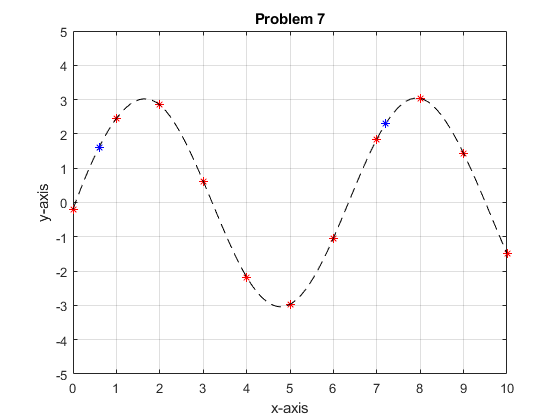

%  your code goes here
clc;clf;clear;
x=[ 0 1 2 3 4 5 6 7 8 9 10];
y=[-0.1960 2.4519 2.8456 0.6230 -2.1724 -2.9705 -1.0376 1.8493 3.0359 1.4313 -1.4892];

%plot points using red stars
plot(x,y,'*r')
title('Problem 7');grid on;axis([0,10,-5,5]);xlabel('x-axis');ylabel('y-axis');

% ---- Cubic spline ----
xp = linspace(0,10);
ps=spline(x,y);
ys=ppval(ps,xp);
hold on;plot(xp,ys,'--k');hold off;
xe=[0.6 7.2];
ye=ppval(ps,xe);
hold on; plot(xe,ye,'*b'); hold off;


% % Vandermonde Matrix
%     %interpolate points
% I1 = ones(length(x),1);
% X = [ (x.^3)' (x.^2)' x' I1];
%     %coefficients of poly
% u=X\y';
%     %define function
% f=@(x) u(1)*x.^3 + u(2)*x.^2 + u(3)*x + u(4);
%     %plot cubic function over range
% xp = linspace(0,10);
% hold on; plot(xp,f(xp),'--b'); hold off;
% 
% % higher order polynomial ?
% pp=polyfit(x,y,9);
% xp=linspace(0,10);
% yp=polyval(pp,xp);
% hold on; plot(xp,yp,'.g'); hold off

## Problem 8

Given the points defined by

x=[ 0 1 2 3 4 5 6 7 8 9 10] 

and

y(x)=[3.3333, 2.5000,0.9091,0.3333,0.1493,0.0781,0.0457,0.0289,0.0194,0.0137,0.0100];

Plot the points.

Compute the cubic spline that interpolates the points and plot it,

Use the cubic spline to estimate the value y(2.7) and y(6.3)

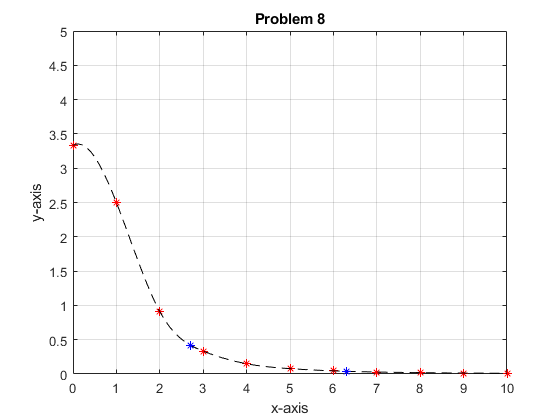

%  your code goes here
clc;clf;clear;
x=[ 0 1 2 3 4 5 6 7 8 9 10];
y=[3.3333, 2.5000,0.9091,0.3333,0.1493,0.0781,0.0457,0.0289,0.0194,0.0137,0.0100];

%plot points using red stars
plot(x,y,'*r')
title('Problem 8');grid on;axis([0,10,0,5]);xlabel('x-axis');ylabel('y-axis');

% ---------- Cubic spline --------------
xp = linspace(0,10);
ps=spline(x,y);
ys=ppval(ps,xp);
hold on;plot(xp,ys,'--k');hold off;
xe=[2.7 6.3];
ye=ppval(ps,xe);
hold on; plot(xe,ye,'*b'); hold off;

## Problem 9

Consider the function


$$f\left(x\right)=\frac{1}{1+x^2 }$$


and the points x=[-5 -4 -3 -2 -1 0 1 2 3 4 5].

Determine the best-fit fourth-order polynomial that interpolates the graph at the points (x,f(x)).   Plot both the points, and the interpolating polynomial over the interval [-5,5] on the same graph.

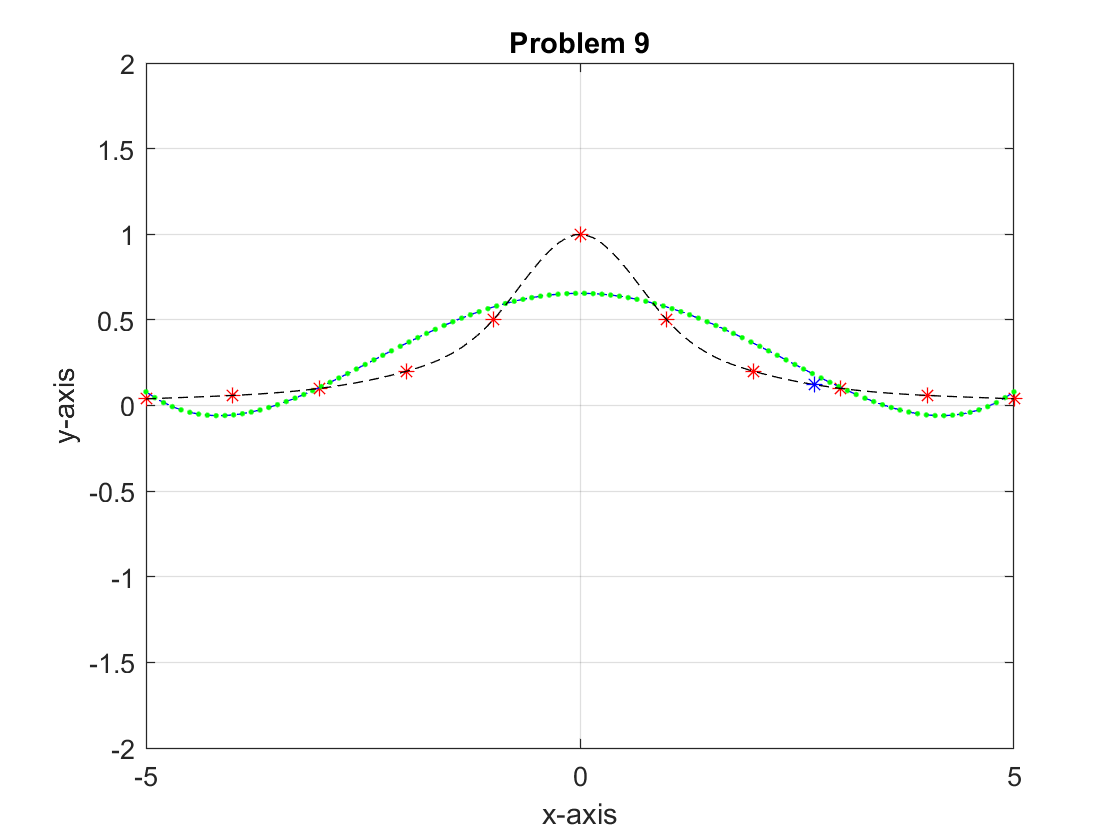

%  your code goes here
clc;clf;clear;
x=[-5 -4 -3 -2 -1 0 1 2 3 4 5];
y= 1./(1+x.^2);

%plot points using red stars
plot(x,y,'*r')
title('Problem 9');grid on;axis([-5,5,-2,2]);xlabel('x-axis');ylabel('y-axis');

% ---------------- Vandermonde Matrix ----------------------
    %interpolate points
I1 = ones(length(x),1);
X = [ (x.^4)' (x.^3)' (x.^2)' x' I1];
    %coefficients of poly
u=X\y';
    %define function
f=@(x) u(1)*x.^4 + u(2)*x.^3 + u(3)*x.^2 + u(4)*x + u(5);
    %plot cubic function over range
xp = linspace(-5,5);
hold on; plot(xp,f(xp),'--b'); hold off;

% higher order polynomial ?
pp=polyfit(x,y,4);
% xp=linspace(0,10);
yp=polyval(pp,xp);
hold on; plot(xp,yp,'.g'); hold off

% ---------- Cubic spline --------------
xp = linspace(-5,5);
ps=spline(x,y);
ys=ppval(ps,xp);
hold on;plot(xp,ys,'--k');hold off;
xe=[2.7 6.3];
ye=ppval(ps,xe);
hold on; plot(xe,ye,'*b'); hold off;

## Problem 10

Find the minimum of the function 


$$f\left(x\right)=\frac{x^3 -x^2 -7}{x-1}$$


on the interval [-2,0].   Use a method we learned in class and then check your result with an appropriate MATLAB function.

% Your code goes here
f=@(x) (x.^3 - x.^2 - 7)./(x-1);
fplot(f,[-2 0]); hold on; grid on; hold off; title('Problem 10')

% ------------ Golden Search ---------------
ax = [-2];     % Left endpoints
dx = [0];      % Right endpoints

%for n=1:20
for m=1:length(ax)
    a=ax(m);
    d=dx(m);
    while abs(a-d)>1e-5
        b=a+(d-a)/3;
        c=a+2*(d-a)/3;
        
        if f(b)>f(c)
            a=b; 
        else
            d=c;
        end
    end
    xmin=(a+d)/2;
    ymin=f(xmin);
    hold on;plot(xmin,ymin,'ok');hold off;
    fprintf('Using Golden search \n Minumim %i: x = %5.3f y = %5.3f',m,xmin,ymin)
end

Using Golden search 
 Minumim 1: x = -0.935 y = 4.492

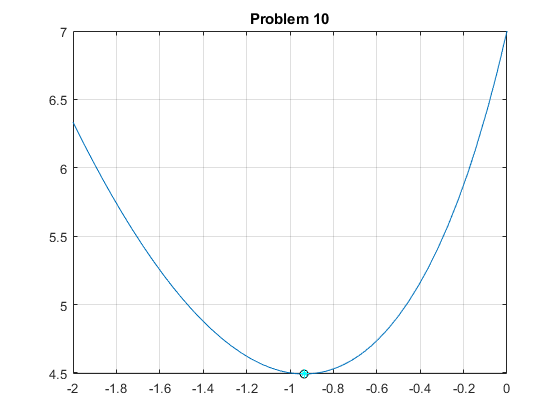

Using fminsearch 
 Minumun 1: for x = -0.935 y= 4.492


% ----------- fminsearch -------------
hx=[-2.2];
for m=1:length(hx)
    h=hx(m);
    xmin1=fminsearch(f,h);
    ymin1=f(xmin1);
    fprintf('Using fminsearch \n Minumun %i: for x = %5.3f y= %5.3f',m,xmin1,ymin1)
    hold on; plot(xmin1,ymin1,'*c'); hold off;
end

## Problem 11

Find the relative minimum of the function 


$$f\left(x\right)={x*e}^x$$


on the interval [-2,0].   Use a method we learned in class and then check your result with an appropriate MATLAB function.

clc;clear;clf;
% your code goes here
f=@(x) x.*exp(x);
fplot(f,[-2 0]); hold on; grid on; hold off; title('Problem 11')

% ----------- Golden Search ------------
ax = [-1.2];     % Left endpoints
dx = [-0.5];      % Right endpoints


for m=1:length(ax)
    a=ax(m);
    d=dx(m);
    while abs(a-d)>1e-5
        b=a+(d-a)/3;
        c=a+2*(d-a)/3;
        
        if f(b)>f(c)
            a=b;
        else
            d=c;
        end
    end
    xmin=(a+d)/2;
    ymin=f(xmin);
    hold on;plot(xmin,ymin,'ok');hold off;
    fprintf('Using Golden search \n Minumim %i: x = %f y = %f',m,xmin,ymin)
    
end

Using Golden search 
 Minumim 1: x = -0.999999 y = -0.367879

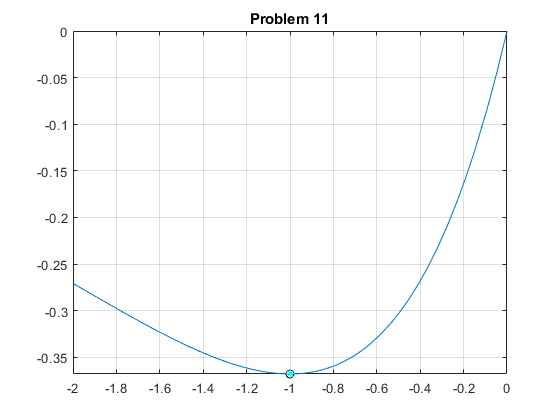

Using fminsearch 
 Minumun 1: for x = -1.000000 y= -0.367879


% ------------ fminsearch --------------------
hx=[-1]; % initial guess for minumum
for m=1:length(hx)
    h=hx(m);
    xmin1=fminsearch(f,h);
    ymin1=f(xmin1);
    fprintf('Using fminsearch \n Minumun %i: for x = %f y= %f',m,xmin1,ymin1)
    hold on; plot(xmin1,ymin1,'*c'); hold off;
end

## Problem 12

A closed rectangular box with a square base is to have a volume of 2250 cubic inches.  The materials for the top and bottom of the box will cost $2 per square inch, and the material for the sides will cost $3 per square inch.  Find numerically the length of the side of the square base of the box with least cost.

Define variables

clc;clear;clf;
% define variables here
% x and y are dimensions of the square base
% v=@(x,y) (x.^2).*y - 2250;
% could use fminbdn; fminsearch; golden search

Solve

% your code goes here
%plot cost as a function of x

TC=@(x) 4*x.^2 + 12*x.*(2250./x.^2)

TC = function_handle with value:
    @(x)4*x.^2+12*x.*(2250./x.^2)


x=linspace(0,100);
plot(x,TC(x))

% find minumun cost using fminbnd
xmin=fminbnd(TC,10,20)

xmin =           15.0000122616965


ymin=TC(xmin)

ymin =            2700.0000000018


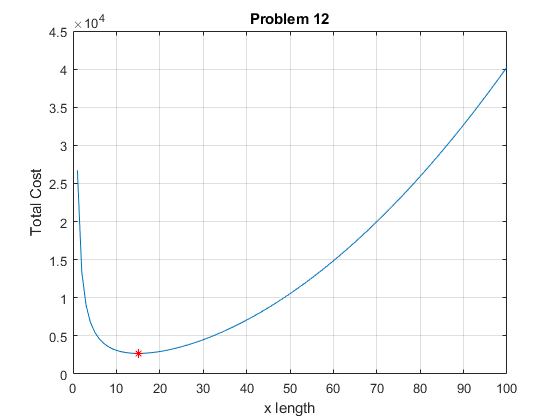

hold on; plot(xmin,ymin,'*r'); title('Problem 12'); xlabel('x length'); ylabel('Total Cost'); grid on; hold off;

fprintf('The side of the square base will be %3.2f inches long the box will cost $ %5.2f',xmin,ymin)

The side of the square base will be 15.00 inches long the box will cost $ 2700.00

## Problem 13

Solve


$$\frac{d}{\mathrm{d}t}y=\frac{1+y^2 }{\textrm{ty}}$$
 

over the interval [2,3] with y(2)=3.

Use a method we learned in class and then check your result with an appropriate MATLAB function.

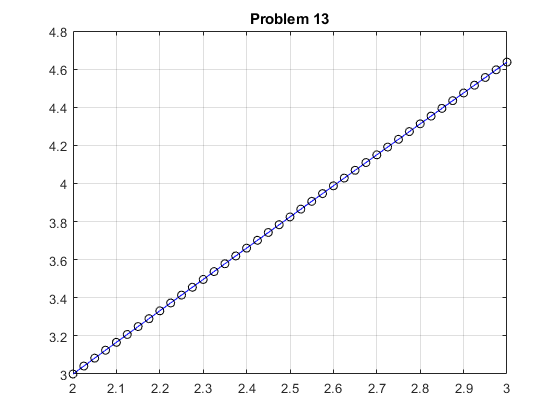

clc;clear;clf;
% your code goes here
dydt=@(t,y) (1+y.^2)./(t.*y);
    % Initial conditions
y0=3;
t0=2; tf=3;

% --------- Euler's Technique ----------
N=1000;
t=linspace(t0,tf,N+1); dt=(tf-t0)/N;

y=zeros(N+1,1);
y(1)=y0;

for n=1:N
    y(n+1)=y(n)+dt*dydt(t(n),y(n));
end
plot(t,y,'-b'); grid on; title('Problem 13');


% ---------- ODE45 ----------
[ts,ys]=ode45(dydt,[t0,tf],y0);

hold on; plot(ts,ys,'ok'); hold off;

## Problem 14

Solve


$$\frac{d}{\mathrm{d}t}y=\sin \left(t\right)+e^t$$
 

over the interval [0,5] with y(0)=1.

Use a method we learned in class and then check your result with an appropriate MATLAB function.

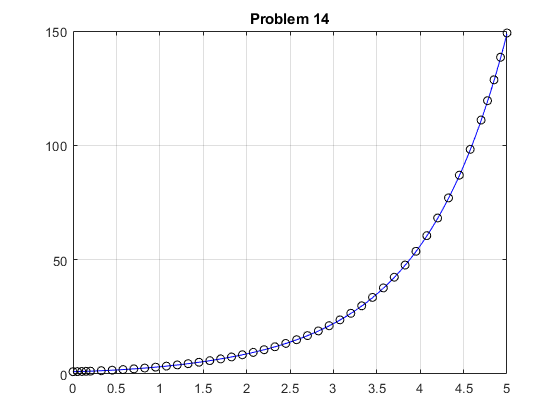

clc;clear;clf;
% your code goes here
dydt=@(t,y) sin(t) + exp(t);
    % Initial conditions
y0=1;
t0=0; tf=5;

% --------- Euler's Technique ----------
N=1000;
t=linspace(t0,tf,N+1); dt=(tf-t0)/N;

y=zeros(N+1,1);
y(1)=y0;

for n=1:N
    y(n+1)=y(n)+dt*dydt(t(n),y(n));
end
plot(t,y,'-b'); grid on; title('Problem 14');


% ---------- ODE45 ----------
[ts,ys]=ode45(dydt,[t0,tf],y0);

hold on; plot(ts,ys,'ok'); hold off;

## Problem 15

Solve the system


$$\frac{\textrm{dx}}{\textrm{dt}}=t-y+x$$



$$\frac{\textrm{dy}}{\textrm{dt}}=x+2y$$


with initial conditions:


$$x\left(0\right)=1$$



$$y\left(0\right)=0$$


over the interval [0,1]

Use Euler's method, then check your result with the appropriate MATLAB function

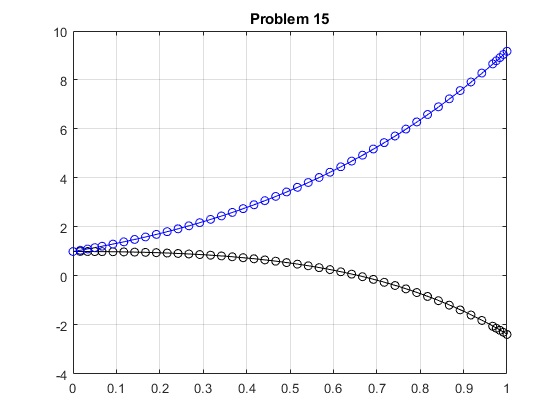

clc;clear;clf;
% your code goes here
dxdt=@(t,x,y) t - y + x;
dydt=@(t,x,y) x + 2*y;

    % Initial conditions
x0=1; y0=1;
t0=0; tf=1;

% --------- Euler's Technique ----------
N=1000;
t=linspace(t0,tf,N+1); dt=(tf-t0)/N;

x=zeros(N+1,1); y=zeros(N+1,1);
x(1)=x0;        y(1)=y0;

for n=1:N
    x(n+1)=x(n)+dt*dxdt(t(n),x(n),y(n));
    y(n+1)=y(n)+dt*dydt(t(n),x(n),y(n));
end
plot(t,x,'-k'); grid on; title('Problem 15');
hold on; plot(t,y,'-b'); hold off;

% ---------- ODE45 ----------
dzdt= @(t,z) [ dxdt(t,z(1),z(2)) ; dydt(t,z(1),z(2)) ];
z0=[x0,y0];

[ts,zs]=ode45(dzdt,[t0,tf],z0);

hold on; plot(ts,zs(:,1),'ok',ts,zs(:,2),'ob'); hold off;

## Problem 16

Solve the system


$$\frac{\textrm{dx}}{\textrm{dt}}=2-4y+\textrm{xsin}\left(t\right)$$



$$\frac{\textrm{dy}}{\textrm{dt}}=x$$


with initial conditions:


$$x\left(0\right)=0$$



$$y\left(0\right)=0$$


over the interval [0,1]

Use Euler's method, then check your result with the appropriate MATLAB function

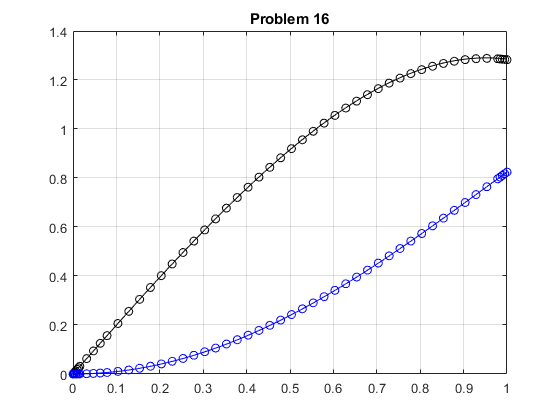

clc;clear;clf;

% your code goes here
dxdt=@(t,x,y) 2-4*y+x.*sin(t);
dydt=@(t,x,y) x;

    % Initial conditions
x0=0; y0=0;
t0=0; tf=1;

% --------- Euler's Technique ----------
N=1000;
t=linspace(t0,tf,N+1); dt=(tf-t0)/N;

x=zeros(N+1,1); y=zeros(N+1,1);
x(1)=x0;        y(1)=y0;

for n=1:N
    x(n+1)=x(n)+dt*dxdt(t(n),x(n),y(n));
    y(n+1)=y(n)+dt*dydt(t(n),x(n),y(n));
end
plot(t,x,'-k'); grid on; title('Problem 16');
hold on; plot(t,y,'-b'); hold off;

% ---------- ODE45 ----------
dzdt= @(t,z) [ dxdt(t,z(1),z(2)) ; dydt(t,z(1),z(2)) ];
z0=[x0,y0];

[ts,zs]=ode45(dzdt,[t0,tf],z0);

hold on; plot(ts,zs(:,1),'ok',ts,zs(:,2),'ob'); hold off;

## Problem 17

Where does the minimum of the function


$$f\left(x,y\right)={\left(x+2\right)}^2 +{\left(y-1\right)}^2 +2\sin \left(\textrm{xy}\right)$$


occur?  What is the value of the function at its minimum point?  Plot the function and the location of its minimum value on a contour plot.

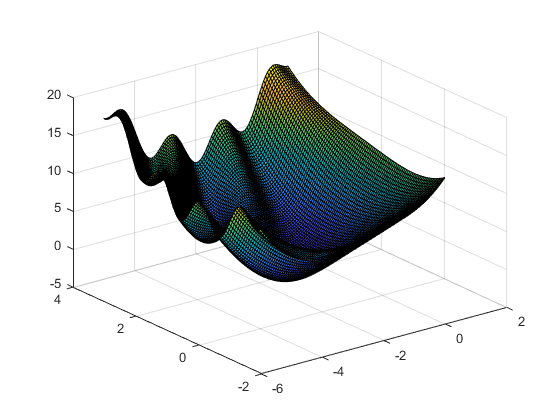

clc;clf;clear;
% your code goes here
f=@(x,y) (x+2).^2 + (y-1).^2 + 2*sin(x.*y);

x=linspace(-5,1); % x min to x max
y=linspace(-1,4); % y min to y max
[X,Y]=meshgrid(x,y);
surf(X,Y,f(X,Y));

contour(X,Y,f(X,Y),[-5:5],'ShowText','on'); grid on; title('Problem 17')

% --------- Steepest Descent ----------
dfdx=@(x,y) 2*(x+2) + 2*y.*cos(x.*y);
dfdy=@(x,y) 2*(y-1) + 2*x.*cos(x.*y);
gradz=@(z) [dfdx(z(1),z(2)) ; dfdy(z(1),z(2))];
z0=[-1;1.5]; % [x;y] guess 

    % use iterative method
zm=z0; gamma=0.01; 
    % plot initial guess
hold on; plot(zm(1),zm(2),'ok'); hold off;
    % iterative loop
for n=1:400
    zm=zm-gamma*gradz(zm);
    hold on; plot(zm(1),zm(2),'*g');hold off;
end
hold on; plot(zm(1),zm(2),'*r');hold off;
fprintf('Using Steepest Descent: xmin = %f ymin = %f f(x,y)min = %f',zm(1),zm(2),f(zm(1),zm(2)))

Using Steepest Descent: xmin = -1.934148 ymin = 0.851843 f(x,y)min = -1.967819

% disp(zm)
% f(zm(1),zm(2))

% ----------- fminsearch --------------
fz=@(z) f(z(1),z(2));
zsoln=fminsearch(fz,z0);
hold on; plot(zsoln(1),zsoln(2),'>b')
fprintf('Using fminsearch: xmin = %f ymin = %f f(x,y)min = %f',zsoln(1),zsoln(2),fz(zsoln))

Using fminsearch: xmin = -1.934662 ymin = 0.851598 f(x,y)min = -1.967819

% fz(zsoln)

% ------------ fminunc --------------
% we can also use fminunc if we wanted to:
 %use matlab function to find the minimum
fz=@(z) f(z(1),z(2));
 
[zsoln1,fminumun]=fminunc(fz,z0);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



fprintf('Using fminunc: xmin = %f ymin= %f f(x,y)min = %f',zsoln1(1),zsoln(2),fminumun)

Using fminunc: xmin = -1.934678 ymin= 0.851598 f(x,y)min = -1.967819

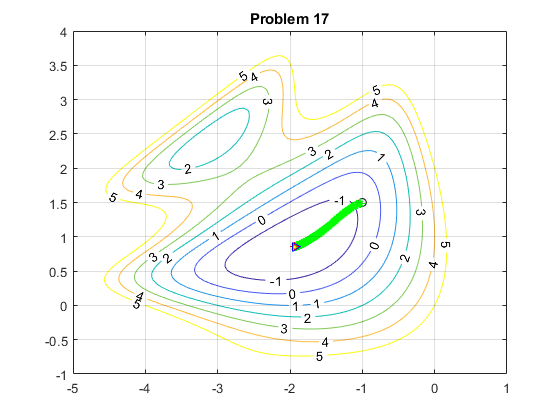

hold on; plot(zsoln1(1),zsoln1(2),'.y'); hold off;

## Problem 18

Solve these equations simultaneously using Newton's Method.    


$$5x^2 +9xy+5y^2 =30$$



$$x^3 =y+1$$


Find all solutions.   Repeat Problem, using MATLAB fsolve, to confirm your results.

clc;clear;clf;
% your code goes here
u=@(x,y) 5*x.^2 + 9*x.*y + 5*y.^2 - 30;
v=@(x,y) x.^3 - y - 1;

x=linspace(-10,10);
y=linspace(-10,10);
[X,Y]=meshgrid(x,y);
contour(X,Y,u(X,Y),[0,0],'-b'); grid on; title('Problem 18');
hold on; contour(X,Y,v(X,Y),[0,0],'-r'); hold off;

% --------------- Newtons Method ----------------
    % determine how many solutions and about where they are
z0=zeros(2,2); zsoln=zeros(2,2);
z0(:,1)=[-0.8,-1.6]; % [x1,y1]
z0(:,2)=[1,1]; % [x2,y2]
    % Jacobian
dudx=@(x,y) 10*x +  9*y;
dudy=@(x,y) 9*x + 10*y;
dvdx=@(x,y) 3*x.^2;
dvdy=@(x,y) -y;
J=@(x,y)[dudx(x,y),dudy(x,y);dvdx(x,y),dvdy(x,y)];
Jz=@(z)J(z(1),z(2));
    % vectorize
w=@(z) [u(z(1),z(2));v(z(1),z(2))];
    % Initialize the estimate and proceed through iterative loop
for m=1:length(z0)                                      %   How many solutions
    zn=z0(:,m);
    hold on; plot(zn(1),zn(2),'*r');hold off; 
    for n=1:10                                          %   Core Algorithm
        zn=zn-Jz(zn)\w(zn);
        hold on; plot(zn(1),zn(2),'*r');hold off;
    end
    zsoln(:,m)=zn;
end
    % Display Result
for m=1:length(zsoln)
    W=w(zsoln(:,m));
    fprintf('Newtons Method: solution %i is: x = %6.4f  y = %6.4f   u = %6.4f   v = %6.4f  \n',m,zsoln(1,m),zsoln(2,m),W(1),W(2));
end

Newtons Method: solution 1 is: x = -2.7599  y = -0.2590   u = 14.8537   v = -21.7631  
Newtons Method: solution 2 is: x = 1.3026  y = 1.2104   u = 0.0000   v = 0.0000  


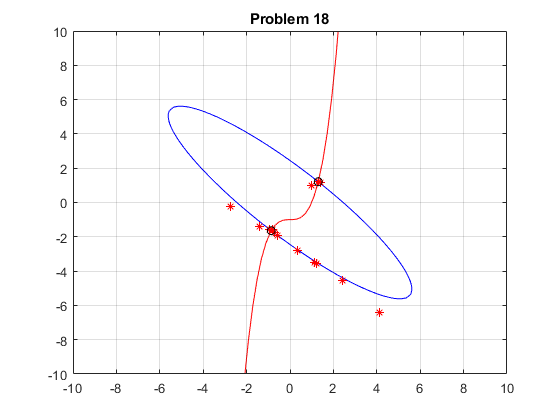


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fsolve: solution 1: x = -0.86331 y = -1.64343


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fsolve: solution 2: x = 1.30264 y = 1.21040


% ---------------- fsolve -----------------
wz=@(z) [u(z(1),z(2));v(z(1),z(2))];
    % Initial guess [x;y]
z1 = [-1 1;
      -1 1];
[N,M]=size(z1);
for m=1:M
    z=z1(:,m);
    solution = fsolve(wz,z);
    fprintf('fsolve: solution %i: x = %5.5f y = %5.5f',m,solution(1),solution(2))
    hold on; plot(solution(1),solution(2),'ok'); hold off;
end

## Problem 19

Find the minimum of the function


$$p\left(x\right)=x^4 +2x^3 -2x^2 +1$$


Use a golden search algorithm.  Repeat Problem, using MATLAB fminsearch, to confirm your results.

clc;clf;clear;
% your code goes here
f=@(x) x.^4 + 2*x.^3 - 2*x.^2 + 1;
fplot(f,[-3 2]); hold on; grid on; hold off; title('Problem 19')

% ----------- Golden Search ------------
ax = [-3];     % Left endpoints
dx = [0];      % Right endpoints


for m=1:length(ax)
    a=ax(m);
    d=dx(m);
    while abs(a-d)>1e-5
        b=a+(d-a)/3;
        c=a+2*(d-a)/3;
        
        if f(b)>f(c)
            a=b;
        else
            d=c;
        end
    end
    xmin=(a+d)/2;
    ymin=f(xmin);
    hold on;plot(xmin,ymin,'ok');hold off;
    fprintf('Using Golden search \n Minumim %i: x = %f y = %f',m,xmin,ymin)
    
end

Using Golden search 
 Minumim 1: x = -2.000000 y = -7.000000

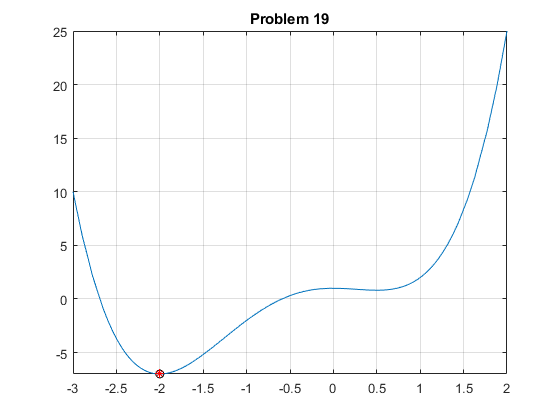

Using fminsearch 
 Minumun 1: for x = -2.000000 y= -7.000000


% ------------ fminsearch --------------------
hx=[-2]; % initial guess for minumum
for m=1:length(hx)
    h=hx(m);
    xmin1=fminsearch(f,h);
    ymin1=f(xmin1);
    fprintf('Using fminsearch \n Minumun %i: for x = %f y= %f',m,xmin1,ymin1)
    hold on; plot(xmin1,ymin1,'*r'); hold off;
end

## Problem 20

Given the data set {s,z(s)} below.   

Do the following:

- Plot the data

- Use a spline to estimate the value of z, for values of s = 0.5, 1.0, 1.5, 2.0, 2.5 and 3.0.    

- Display and plot the results.

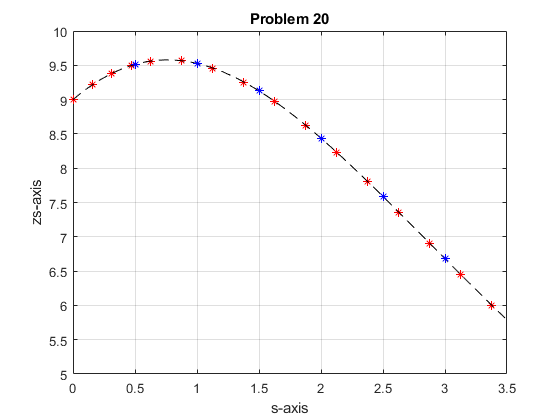

%  your code goes here
clc;clf;clear;
s=[0,0.157,0.314,0.472,0.629,0.879,1.129,1.379,1.629,1.879,2.129,2.379,2.629,2.879,3.129,3.379];
zs=[9,9.216,9.382,9.497,9.562,9.566,9.459,9.255,8.971,8.623,8.228,7.802,7.356,6.901,6.447,6.000];

%plot points using red stars
plot(s,zs,'*r')
title('Problem 20');grid on;axis([0,3.5,5,10]);xlabel('s-axis');ylabel('zs-axis');

% ---- Cubic spline ----
xp = linspace(0,3.5);
    %compute spline coefficient
pp=spline(s,zs); % pp is a peicwise polynomial
zp=ppval(pp,xp);
    %plot the spline
hold on;plot(xp,zp,'--k');hold off;
    %estimate values of zs for given points
sx=[0.5 1 1.5 2 2.5 3];
sy=ppval(pp,sx);
hold on; plot(sx,sy,'*b'); hold off;

## Problem 21

Solve the system over the interval $0\le x\le 10$


$$\frac{d}{\mathrm{d}t}x=-axy+by$$



$$\frac{d}{\mathrm{d}t}y=-cy+dxy$$


where


$$a=0\ldotp 04;\;\;b=0\ldotp 05;\;\;\;c=0\ldotp 60;\;\;\;d=0\ldotp 07$$


and with initial conditions $\textrm{at}\;t=0,{\;x}_0 =11\;\;\textrm{and}\;\;\;y_0 =9$

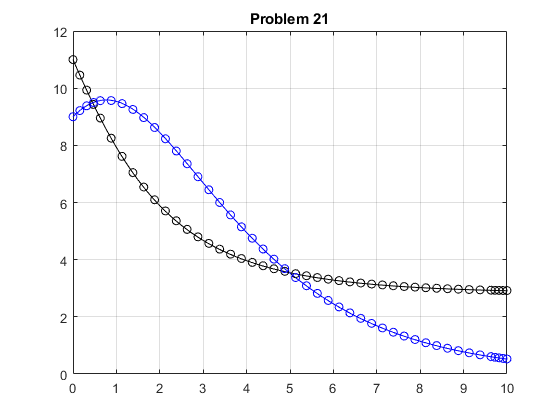

clc;clear;clf;
    % Constants
a=0.04; b=0.05; c=0.60; d=0.07;

dxdt=@(t,x,y) -a*x.*y + b*y;
dydt=@(t,x,y) -c*y + d*x.*y;

    % Initial conditions
x0=11; y0=9;
t0=0; tf=10;

% --------- Euler's Technique ----------
N=1000;
t=linspace(t0,tf,N+1); dt=(tf-t0)/N;

x=zeros(N+1,1); y=zeros(N+1,1);
x(1)=x0;        y(1)=y0;

for n=1:N
    x(n+1)=x(n)+dt*dxdt(t(n),x(n),y(n));
    y(n+1)=y(n)+dt*dydt(t(n),x(n),y(n));
end
plot(t,x,'-k'); grid on; title('Problem 21');
hold on; plot(t,y,'-b'); hold off;

% ---------- ODE45 ----------
dzdt= @(t,z) [ dxdt(t,z(1),z(2)) ; dydt(t,z(1),z(2)) ];
z0=[x0,y0];

[ts,zs]=ode45(dzdt,[t0,tf],z0);

hold on; plot(ts,zs(:,1),'ok',ts,zs(:,2),'ob'); hold off;

## Problem 22

Find the minimum of the function


$$f\left(x,y\right)=x^2 +xy+y^2 +e^{x+y}$$


using a steepest descent algorithm.   Display a contour plot of the function and denote the location of the minimum with a red star.   Repeat Problem using MATLAB fminsearch to confirm your result.

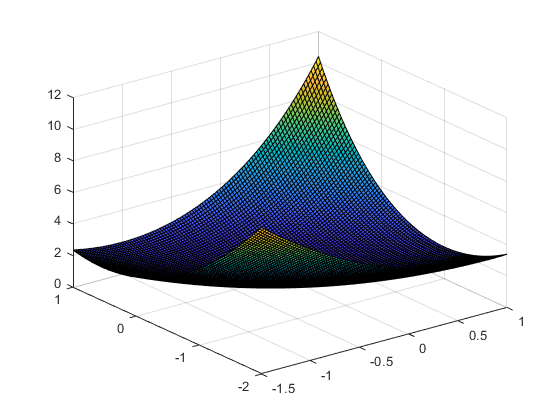

clear;clf;clc;
f=@(x,y) x.^2 + x.*y + y.^2 + exp(x+y);
x=linspace(-1.5,1); 
y=linspace(-2,1);
[X,Y]=meshgrid(x,y);
surf(X,Y,f(X,Y));

contour(X,Y,f(X,Y),'ShowText','on'); grid on;

%Use the method of steepest descent
dfdx=@(x,y) 2*x + y + exp(x+y);
dfdy=@(x,y) x + 2*y + exp(x+y);
gradz=@(z) [dfdx(z(1),z(2)) ; dfdy(z(1),z(2))];
z0=[-0.25;-0.25];

% use iterative method
zm=z0; gamma=0.1; hold on; plot(zm(1),zm(2),'ok'); hold off;
for n=1:40
    zm=zm-gamma*gradz(zm);
    hold on; plot(zm(1),zm(2),'*g');hold off;
end
hold on; plot(zm(1),zm(2),'*r');hold off;
disp(zm)

        -0.216281377771992
        -0.216281377771992



f(zm(1),zm(2))

ans =          0.789177036403077



% Fminsearch
fz=@(z) f(z(1),z(2));
zsoln=fminsearch(fz,z0)

zsoln =          -0.21626946022152
        -0.216301350563299


hold on; plot(zsoln(1),zsoln(2),'>b')
fz(zsoln)

ans =          0.789177036727041



% we can also use fminunc if we wanted to:
 %use matlab function to find the minimum
 fz=@(z) f(z(1),z(2));
 z0=[1;1];
 [zsoln1,fminumun]=fminunc(fz,z0)


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


zsoln1 =         -0.216280701556573
        -0.216280701556573


fminumun =          0.789177036405042


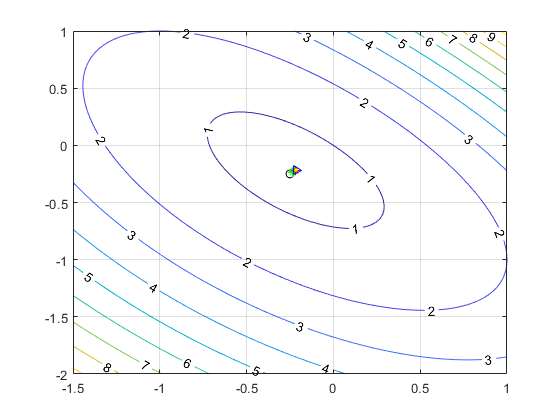

 hold on; plot(zsoln1(1),zsoln1(2),'.y'); hold off;

## Problem 23

Solve the equation for a damped non-linear pendulum


$$\frac{d^2 }{\mathrm{d}t^2 }\theta +b\frac{d}{\mathrm{d}t}\theta +c\sin \left(\theta \right)=0$$


with $b=0\ldotp 5\;;c=1$ and initial conditions of displacement of 0.5 radians and zero velocity.  $\theta_0 =0\ldotp 5;\;v_0 =0$

Plot your results.

clc;clear;clf;
 %  Your code goes here 
b=0.5; c=1;

dOdt=@(t,O,y)y

dOdt = function_handle with value:
    @(t,O,y)y


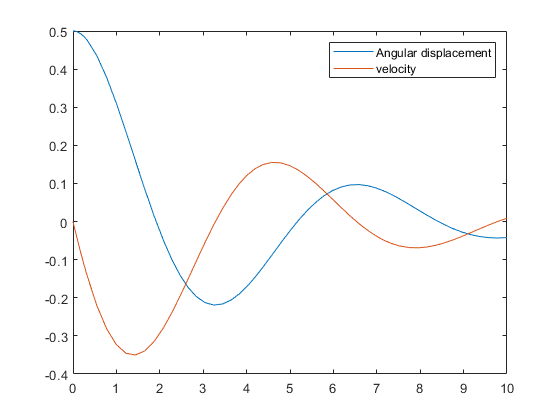

dydt=@(t,O,y)-b*y-c*sin(O);

Oa=0.5;
ya=0;

dzdt=@(t,z) [ dOdt(t,z(1),z(2));dydt(t,z(1),z(2))];
za=[Oa;ya];
[t,z]=ode45(dzdt,[0 10],za);
plot(t,z)
legend('Angular displacement','velocity')

## Problem 24

Solve the equation


$$4xe^{-x} +4\sin \left(2x\right)=5$$


using a bisection routine.  Find all the solutions.

Repeat Problem using MATLAB fzero or fsolve to check your work.

clc; clear; clf;
% Your code goes here

f=@(x) 4*x.*exp(-x) + 4*sin(2*x) - 5;
fplot(f,[0,5]); grid on; xlabel('x axis'); ylabel('y axis'); title('Problem 24');

% -------------- Bisection -------------
    % left and right endpoints 
ax=[0 1]; % left endpoint
cx=[1 2]; % right endpoint
    % Bisection
for m=1:length(ax)
    a=ax(m);
    c=cx(m);
    for n=1:40
        b=(a+c)/2;
        hold on;plot(b,f(b),'*r');hold off;
        if f(b)==0
            a=b;
            c=b;
            break;
        elseif f(a)*f(b)<0
            c=b;
        else
            a=b;
        end
    end
fprintf('Using Bisection: x%i = %3.3f and y%i = %3.3f',m,b,m,f(b))
hold on;plot(b,f(b),'ok');hold off;
end

Using Bisection: x1 = 0.588 and y1 = -0.000

Using Bisection: x2 = 1.030 and y2 = 0.000

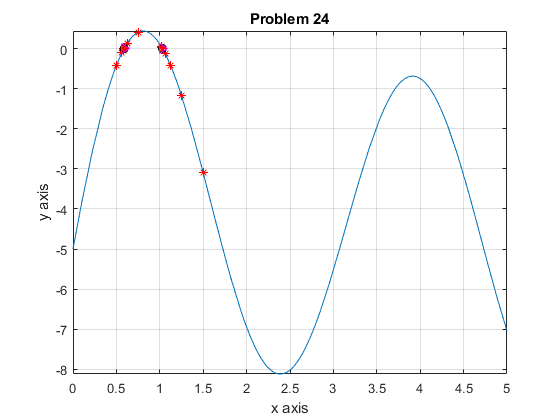

Using fzero: x1 = 0.588 and y1 = -0.000

Using fzero: x2 = 1.030 and y2 = -0.000


% ----------- fzero ----------------------
for i=1:length(ax)
xsoln=fzero(f,[ax(i),cx(i)]);
fprintf('Using fzero: x%i = %3.3f and y%i = %3.3f',i,xsoln,i,f(xsoln))
hold on; plot(xsoln,f(xsoln),'>m'); hold off;
end